# 3. Building Classification Models

## Supervised Learning

Course Example: Heart Disease

% Load the example data
load('heartdisease.mat')
% Is it necessary to apply a classification model to the data?
% Pre-evaluation of the data
[g,c] = kmeans(zscore(heartdataNum{:,1:11}),2);
counts = crosstab(g,heartdataNum.HeartDisease)

counts =    124    65
    67   171


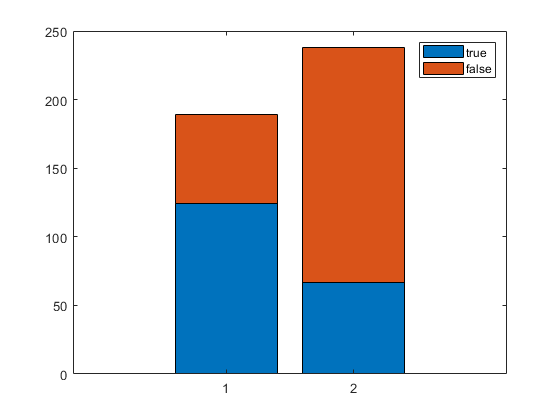

figure
bar(counts,'stacked')
legend([{'true'},{'false'}])

### Training and Validation

% Divide the heart disease into training(80%) and validation(20%) sets
rng(1234)
part = cvpartition(heartdataNum.HeartDisease,'HoldOut',0.2)

part = 홀드아웃 교차 검증 분할
   NumObservations: 427
       NumTestSets: 1
         TrainSize: 342
          TestSize: 85

tridx = training(part);
tdata = heartdataNum(tridx,:);
vdata = heartdataNum(~tridx,:);
tdataAll = heartdataAll(tridx,:);
vdataAll = heartdataAll(~tridx,:);

### 1. Nearest Neighbor Classification(1/2)

The most straightforward way of classification without any assumptions about the underlying distribution of the data

m = fitcknn(tdata,'HeartDisease');
% Why use tdata, not tdataAll? because k-NN does not accept mixed predictors(numeric+categorical).

### Evaluating Classifications

m = fitcknn(tdata,'HeartDisease');
% Measure loss
errKNN_train = resubLoss(m) % Measure loss with the training data

errKNN_train = 0

errKNN_test = loss(m,vdata) % Measure loss with the test(validation) data

errKNN_test = 0.3413

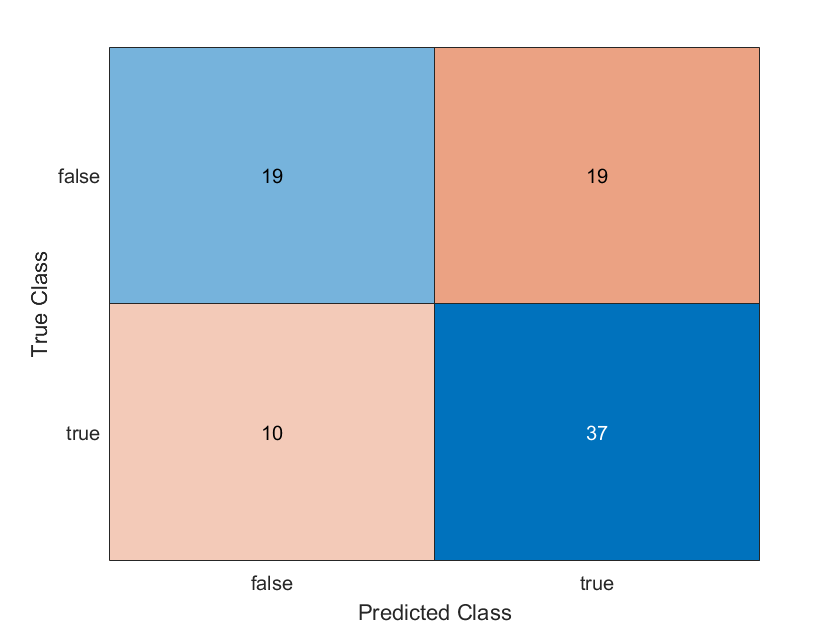


% Visualize prediction accuracy
HDpred = predict(m, vdata);
HDtrue = vdata.HeartDisease;
figure
confusionchart(HDtrue,HDpred)

### 1. Nearest Neighbor Classification(2/2)

% Check overfitting and Update model 1
m.NumNeighbors = 5;% m = fitcknn(tdata,'HeartDisease',"NumNeighbors",5)
errKNN_train = resubLoss(m)

errKNN_train = 0.2222

errKNN_test = loss(m,vdata)

errKNN_test = 0.2471

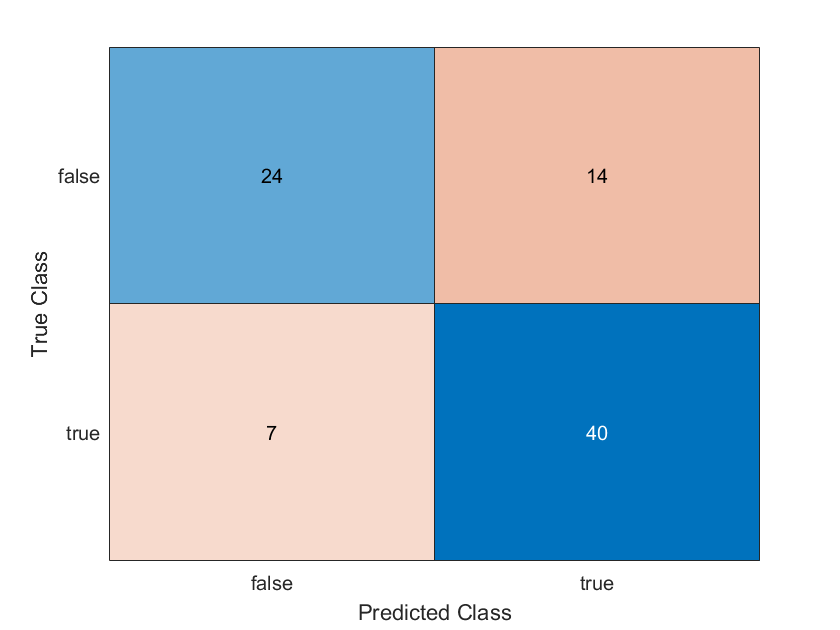

HDpred = predict(m, vdata);
HDtrue = vdata.HeartDisease;
figure
confusionchart(HDtrue,HDpred)


% Update model 2
m.DistanceWeight = 'squaredinverse';
errKNN_train = resubLoss(m)

errKNN_train = 0

errKNN_test = loss(m,vdata)

errKNN_test = 0.2471

### 2. Decision Tree Classification

A decision tree model make a categorical response prediction by following a sequence of binary decisions based on predictor variable value. It does not assume any underlying distributions of the data like k-NN.

A decision tree model is robust to noise data.

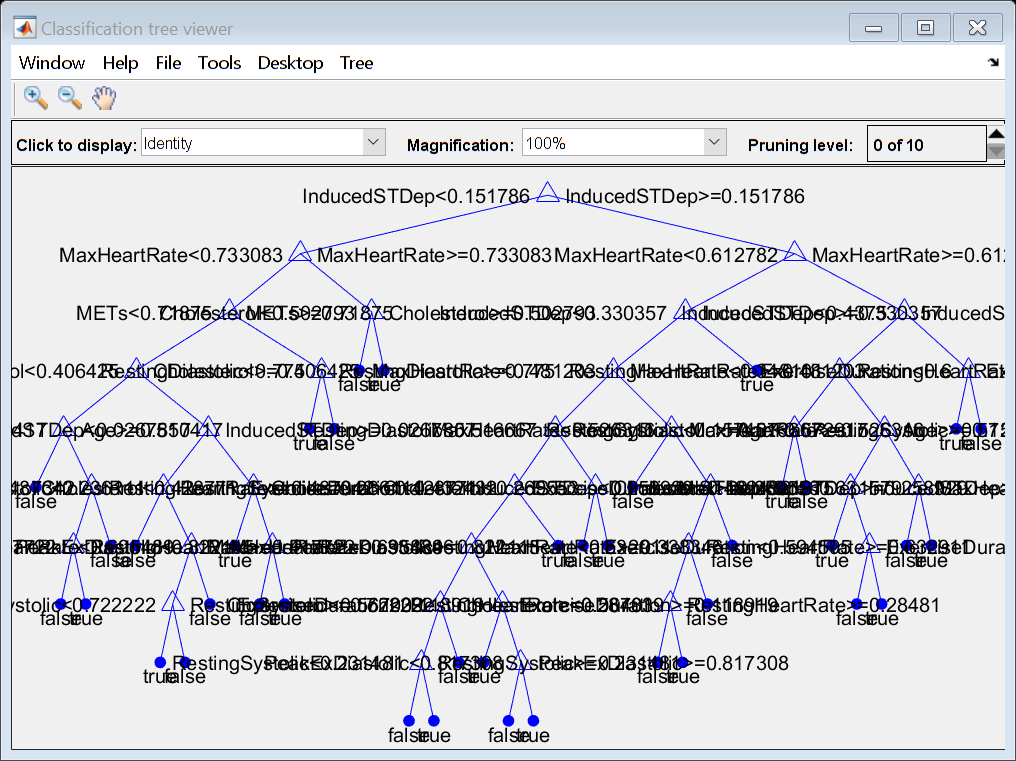

% Fit and evaluate a decision tree model with default settings
m = fitctree(tdata,'HeartDisease');
view(m,'mode','graph')


errDT_train = resubLoss(m)

errDT_train = 0.0789

errDT_test = loss(m,vdata)

errDT_test = 0.2824

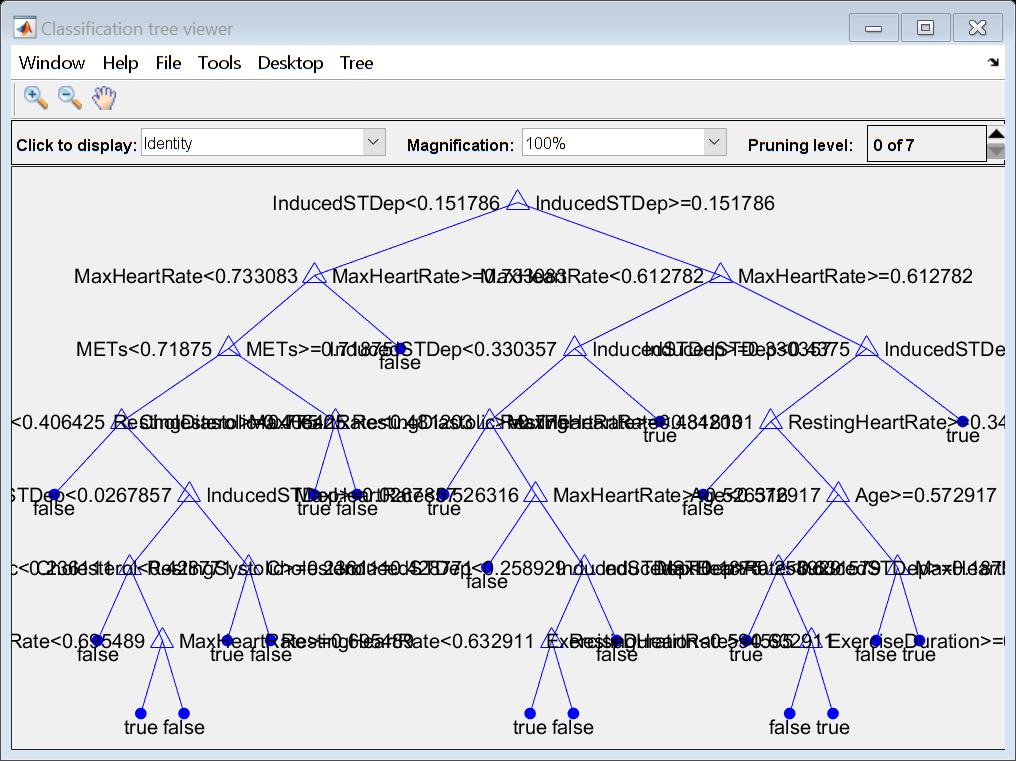

HDpred = predict(m, vdata);
HDtrue = vdata.HeartDisease;

% Check overfitting and update model with 'prune' function
m = prune(m,'Level',3);
view(m,'mode','graph')

errPrunedDT_train = resubLoss(m)

errPrunedDT_train = 0.1404

errPrunedDT_test = loss(m,vdata)

errPrunedDT_test = 0.2000


% Unlike k-NN, a decision tree model accepts mixed data(numeric + categorical)
m = fitctree(tdataAll,'HeartDisease');
errDT_train = resubLoss(m)

errDT_train = 0.0526

errDT_test = loss(m,vdataAll)

errDT_test = 0.2471


m = prune(m,'Level',3);
errPrunedDT_train = resubLoss(m)

errPrunedDT_train = 0.0994

errPrunedDT_test = loss(m,vdataAll)

errPrunedDT_test = 0.2118

### 3. Naive Bayes Classification

A Naive Bayes model uses Bayes's rule of conditional probability to estimate the probability of a given observation being in each response class. Accordingly, it assumes an underlying distribution of the data. (Note: Each predictor variable should be independent, If not, use a 'Discriminant Analysis')

m = fitcnb(tdata,'HeartDisease');
errNB_train = resubLoss(m)

errNB_train = 0.2982

errNB_test = loss(m,vdata)

errNB_test = 0.2000


% Use kernel smoothing instead of normal distributions
% Kernel smoothing only works for numeric predictor variables
m = fitcnb(tdata,'HeartDisease',"DistributionNames","kernel");
errNB_train = resubLoss(m)

errNB_train = 0.2602

errNB_test = loss(m,vdata)

errNB_test = 0.1765


% Use a mix of numeric and categorical predictors and use kernel smoothing for all numerica predictors
m = fitcnb(tdataAll,'HeartDisease');
errNB_train = resubLoss(m)

errNB_train = 0.2047

errNB_test = loss(m,vdataAll)

errNB_test = 0.1177


dists = [repmat({'kernel'}, 1, 11), repmat({'mvmn'}, 1, 10)];
m = fitcnb(tdataAll,'HeartDisease','DistributionNames',dists);
errNB_train = resubLoss(m)

errNB_train = 0.1959

errNB_test = loss(m,vdataAll)

errNB_test = 0.1412

### 4. Discriminant Analysis

Similar to Naive Bayes, discriminant analysis works by assuming that the observations in each prediction class can be modeled with a normal probability distribution. However, there is no assumption of independence in each predictor.

m=fitcdiscr(tdata,'HeartDisease');
errDA_train = resubLoss(m)

errDA_train = 0.2719

errDA_test = loss(m,vdata)

errDA_test = 0.1765


% Use a quadratic boundary
m=fitcdiscr(tdata,'HeartDisease',"DiscrimType",'quadratic');
errDA_train = resubLoss(m)

errDA_train = 0.2485

errDA_test = loss(m,vdata)

errDA_test = 0.2706

### 5. Support Vector Machines

A SVM model classifies data by finding the best hyperplane that separates all data points

It only works for binary categories (true/false, 0/1, pass/fail)

m=fitcsvm(tdata,'HeartDisease');
errSVM_train = resubLoss(m)

errSVM_train = 0.3012

errSVM_test = loss(m,vdata)

errSVM_test = 0.1647


% Use a nonlinear kernel for variable transformation to apply
% Remember 'KernelFunction' option because it is very useful for most data
m=fitcsvm(tdata,'HeartDisease',"KernelFunction","gaussian");
errSVM_train = resubLoss(m)

errSVM_train = 0.2602

errSVM_test = loss(m,vdata)

errSVM_test = 0.1647

### 5. Multiclass Support Vector Machines

Multiclass SVM by creating an error-correcting output codes (ECOC).

% Linear SVM
m=fitcecoc(tdata,'HeartDisease');
errLinearMSVM_Train=resubLoss(m)

errLinearMSVM_Train = 0.3012

errLinearMSVM_Test=loss(m,vdata)

errLinearMSVM_Test = 0.1647


% Gaussian SVM
t=templateSVM('KernelFunction','gaussian');
m=fitcecoc(tdata,'HeartDisease','Learners',t);
errGaussianMSVM_Train=resubLoss(m)

errGaussianMSVM_Train = 0.2602

errGaussianMSVM_Test=loss(m,vdata)

errGaussianMSVM_Test = 0.1647


% Mixed predictors - Linear 
m=fitcecoc(tdataAll,'HeartDisease');
errLinearMSVM_Train=resubLoss(m)

errLinearMSVM_Train = 0.1901

errLinearMSVM_Test=loss(m,vdataAll)

errLinearMSVM_Test = 0.1530



% Mixed predictors - Gaussian
t=templateSVM('KernelFunction','gaussian');
m=fitcecoc(tdataAll,'HeartDisease','Learners',t);
errGaussianMSVM_Train=resubLoss(m)

errGaussianMSVM_Train = 0.0409

errGaussianMSVM_Test=loss(m,vdataAll)

errGaussianMSVM_Test = 0.1765